# Chapter 2. Vectors and Graphics

clear all
close all

## Vectors

a = [1, 2, 3];
b = [-5, -3, -1];
c = [3, 0, -2];
a + b

ans =     -4    -1     2


5*c

ans =     15     0   -10


dot(a, b)

ans = -14

lengthofa = sqrt(dot(a,a))

lengthofa = 3.7417

norm(a)

ans = 3.7417

norm(b)

ans = 5.9161

norm(c)

ans = 3.6056

syms x y z; pl = [x, y]

$$pl = \left(\begin{array}{cc} x & y \end{array}\right)$$

s1 = [pl, 0]

$$s1 = \left(\begin{array}{ccc} x & y & 0 \end{array}\right)$$

s2 = [x, y, z]

$$s2 = \left(\begin{array}{ccc} x & y & z \end{array}\right)$$

p2 = s2(1:2)

$$p2 = \left(\begin{array}{cc} x & y \end{array}\right)$$

cross(a, b)

ans =      7   -14     7


## Applications of Vectors

phi = acos(dot(a, b)/(norm(a)*norm(b)))

phi = 2.2555

phi*180/pi

ans = 129.2315

(dot(a, b)/dot(b, b))*b

ans =     2.0000    1.2000    0.4000


abs(dot(a, cross(b, c)))

ans = 7

norm(cross(a, c))

ans = 13.1529

## Parametric Curves

Circle

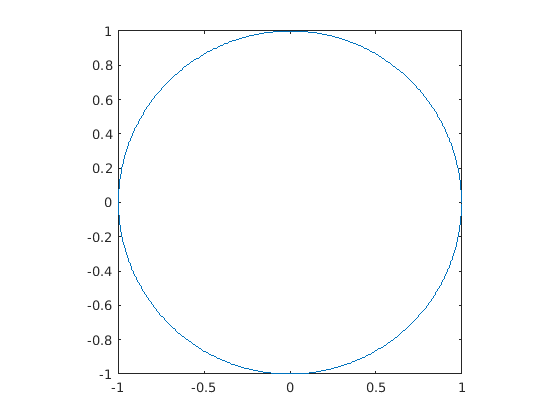

figure; T=0:0.01:2*pi;
plot(cos(T), sin(T)); axis square

Symbolic circle

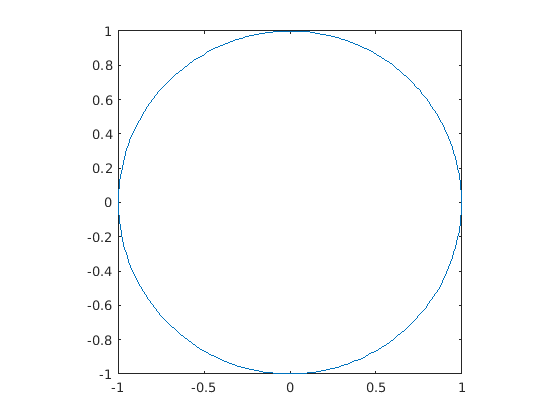

syms t; figure; fplot(cos(t), sin(t), [0, 2*pi]); axis square

Spiral

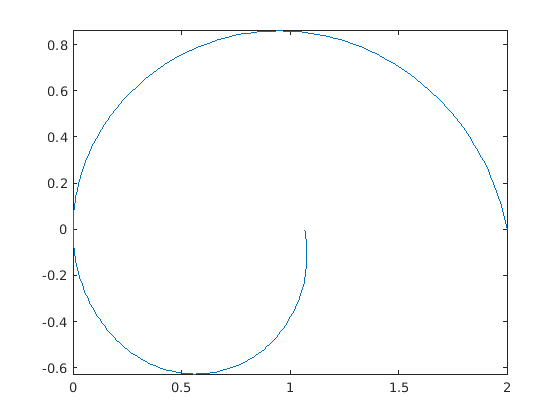

figure; fplot(exp(-t/10)*(1 + cos(t)), exp(-t/10)*(sin(t)), [0 2*pi])

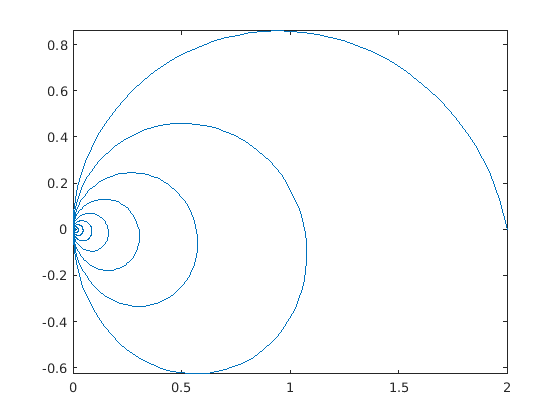


figure; fplot(exp(-t/10)*(1 + cos(t)), exp(-t/10)*(sin(t)), [0 20*pi])

## Viviani's Curve

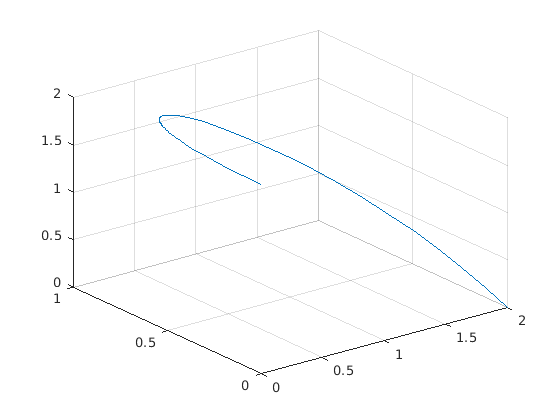

syms t; 
x = 1+cos(t); y = sin(t); z = 2*sin(t/2); figure; fplot3(x, y, z,[0, pi])

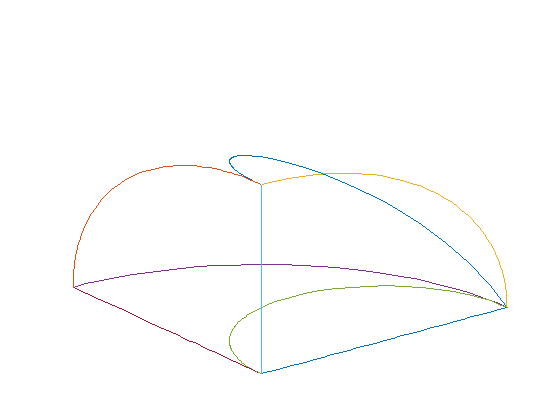

syms t; figure; fplot3(x, y, z,[0, pi])

hold on
fplot3(sym(0), 2*cos(t/2), 2*sin(t/2), [0, pi])
fplot3(2*cos(t/2), sym(0), 2*sin(t/2), [0, pi])
fplot3(2*cos(t/2), 2*sin(t/2), sym(0), [0 pi])
fplot3(1+cos(t), sin(t), sym(0), [0, pi])
fplot3(sym(0), sym(0), t, [0 2]); fplot3(sym(0), t, sym(0), [0 2]); 
fplot3(t, sym(0), sym(0), [0 2])
title(''); xlabel(''); ylabel(''); zlabel('')
grid off; axis off;

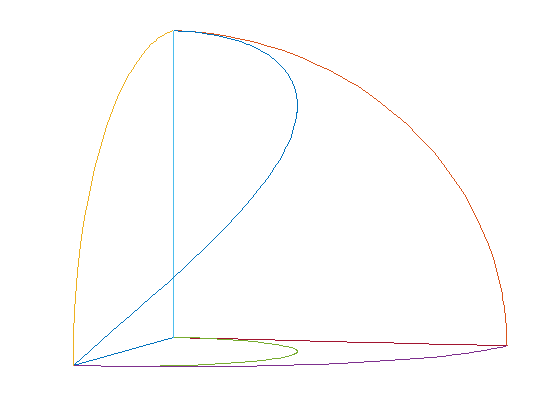

view([10, 3, 1])

## Graphic Surfaces

We give some numerical code, although only symbolic is used in the text.

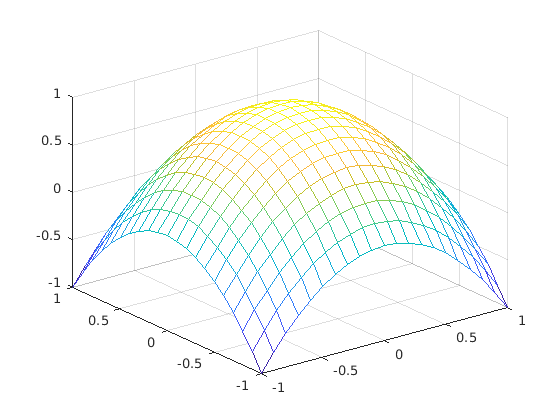

[X, Y] = meshgrid(-1:0.1:1, -1:0.1:1);
Z = 1 - (X.^2 + Y.^2); figure; mesh(X, Y, Z)

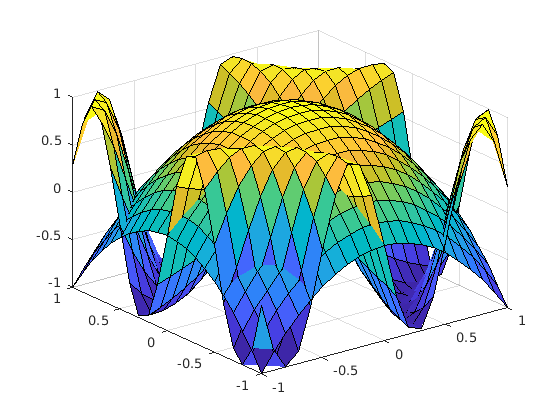


Z2 = 1 - (X.^2 + Y.^2); figure; surf(X, Y, Z2)

Z3=sin(6.*X.*Y); hold on; surf(X, Y, Z3)


g = @(x, y) (1 - (x.^2 + y.^2)).* heaviside(1 - x.^2 - y.^2)

g = function_handle with value:
    @(x,y)(1-(x.^2+y.^2)).*heaviside(1-x.^2-y.^2)


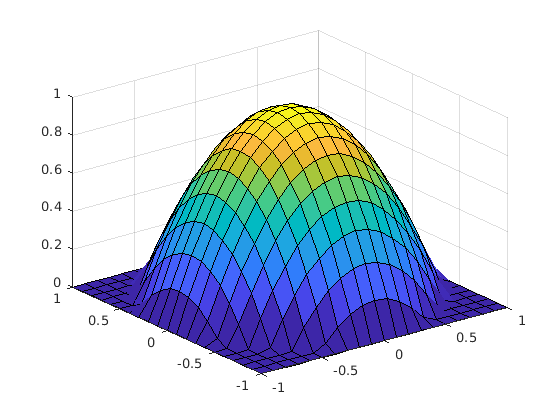

Z4 = g(X, Y); figure; surf(X, Y, Z4)

## Symbolic

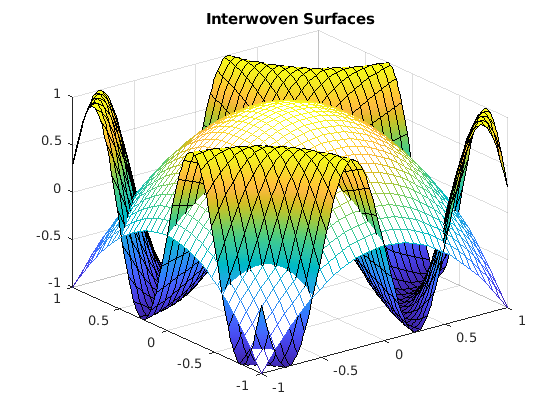

syms x y; figure; fmesh(1 - x^2 - y^2, [-1, 1, -1, 1]) 

hold on; fsurf(sin(6*x*y), [-1, 1, -1, 1])
title('Interwoven Surfaces')

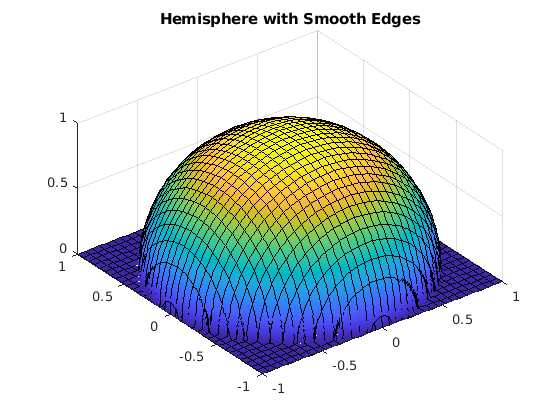

figure; fsurf(sqrt(1-x^2-y^2)*heaviside(1-x^2-y^2), [-1, 1, -1, 1])
title('Hemisphere with Smooth Edges'), axis equal

## Parametric Surfaces

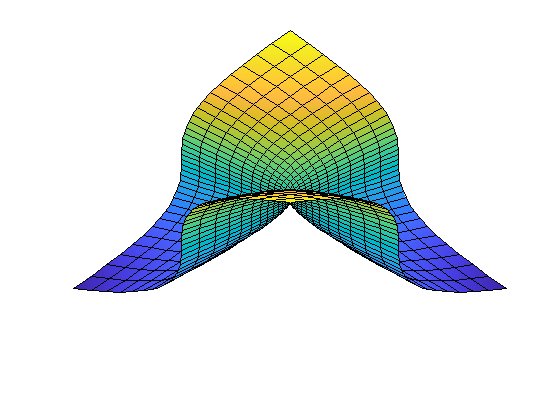

syms u v
figure; fsurf(u^3, v^3, u*v, [-1, 1, -1, 1])
view([1, 1, 1])
title(''); xlabel(''); ylabel(''); zlabel('')
grid off; axis off;